***Martelet Curtis - Giordano Dylan                Groupe 1***

# Rapport TDP1

#### Electronique de Puissance et Thermique

## I) Influence de la tension d'entrée

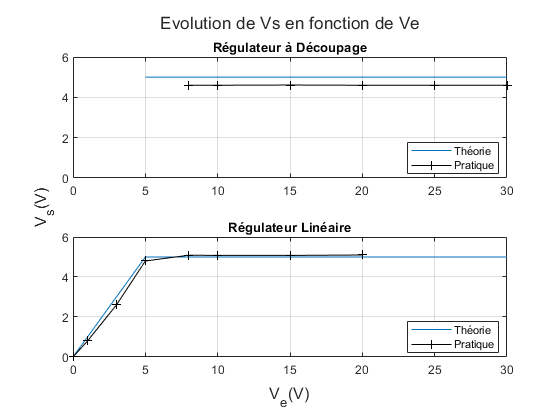

clc

Veth=[0 1 2 3 4 5 10 15 20 25 30];
Vsth=[0 1 2 3 4 5 5  5  5  5  5];

Ve=  [0 1   3   5   8    10   15   20   25  30];
Vs_d=[4.6  4.6  4.61 4.6  4.6 4.6];
Vs_l=[0 0.8 2.6 4.8 5.09 5.08 5.08 5.10];

figure
t = tiledlayout(2,1);
title(t,'Evolution de Vs en fonction de Ve')
xlabel(t,'V_e(V)')
ylabel(t,'V_s(V)')

ax1 = nexttile;
plot(ax1,Veth(6:11),Vsth(6:11),Ve(5:10),Vs_d,'k+-')
title(ax1,'Régulateur à Découpage')
legend('Théorie','Pratique','location','best')
grid on
ylim([0 6])
xlim([0 30])

ax2 = nexttile;
plot(ax2,Veth,Vsth,Ve(1:8),Vs_l,'k+-')
title(ax2,'Régulateur Linéaire')
legend('Théorie','Pratique','location','best')
grid on
ylim([0 6])

On calcul théoriquement que de 0 à 5V, la tension en sortie des régulateur devrait être égale à la tension en entrée. Ce comportement est observé pour le régulateur linéaire, mais pas pour le régulateur à découpage : ce dernier ne délivre aucune tension jusqu'à 8V environ (à cause d'une sécurité).

Quand la tension a dépassé les 20V, le régulateur linéaire est devienu trop chaud pour que l'on puisse exploiter ses valeurs : entre autre, la sécurité thermique a modifié la tension de sortie.

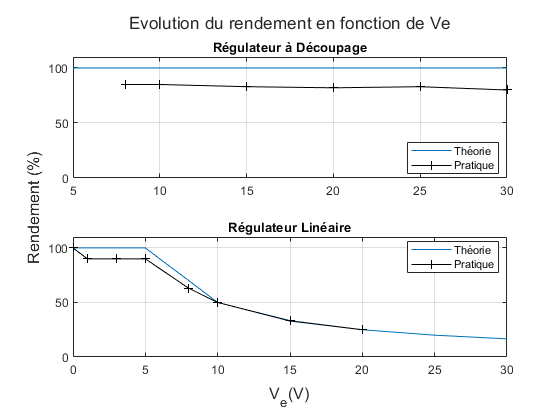

Veth= [5   10  15  20  25  30];
rdmth=[100 100 100 100 100 100];
Ve= [8  10 15 20 25 30];
rdm=[85 85 83 82 83 80];

figure
t = tiledlayout(2,1);
title(t,'Evolution du rendement en fonction de Ve')
xlabel(t,'V_e(V)')
ylabel(t,'Rendement (%)')

ax1 = nexttile;
plot(ax1,Veth, rdmth, Ve, rdm,'k+-')
title(ax1,'Régulateur à Découpage')
legend('Théorie','Pratique','location','best')
% xlabel('V_e(V)')
% ylabel('Rendement (%)')
grid on
ylim([0 110])


Veth =[0   1   2   3   4   5   10 15    20 25 30];
rdmth=[100 100 100 100 100 100 50 33.33 25 20 16.66];
Ve =[0   1  3  5  8  10 15 20];
rdm=[100 90 90 90 63 50 33 25];

ax2 = nexttile;
plot(ax2,Veth, rdmth, Ve, rdm,'k+-')
title(ax2,'Régulateur Linéaire')
legend('Théorie','Pratique','location','best')
% xlabel('V_e(V)')
% ylabel('Rendement (%)')
grid on
ylim([0 110])

Les rendements obtenus en pratique correspondent aux rendements théoriques calculés.

Le rendement du régulateur linéaire est decroissant de 5 à 30V. Cela s'explique par son mode de fonctionnement : ce dernier converti la totalité de la tension mis à disposition par le générateur, ce qui veut dire que si le générateur peut fournir 10V, alors le régulateur aura un rendement de 50% (5/10).

Pour le cas du régulateur à découpage, le rendement théorique est de 100%. En pratique nous avons un rendement autour de 90% mais cela est dû aux différentes pertes dans le circuit. Si laisse de coté ces pertes, on mesurera la même tension des deux cotés du régulateur.

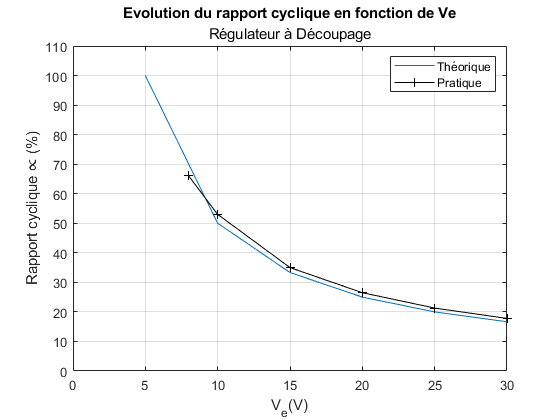

Veth=[5 10 15 20 25 30];
alphath=[100 50 33.33 25 20 16.66];
Ve=[8 10 15 20 25 30];
alpha=[66 53 35 26.5 21.3 17.80];

figure
plot(Veth,alphath,Ve,alpha,'k+-')
axis([0 30 0 100])
title('Evolution du rapport cyclique en fonction de Ve');
subtitle('Régulateur à Découpage')
legend('Théorique','Pratique')
xlabel('V_e(V)')
ylabel("Rapport cyclique ∝ (%)")
grid on
ylim([0 110])

La courbe du rapport cyclique pratique est similaire à celle tracée avec les valeurs théoriques.

Si le régulateur à découpage a une tension d'entrée et de sortie égale qu'importe la tension mise à disposition par le générateur, c'est grâce à la commutation. Pendant une période de temps comprise entre 0 et la totalité de la période de commutation, le transistor dans le régulateur est passant : on a Vs=Ve (le régulateur est passant). Pour le reste de la période, le transistor est bloqué (Vs=0). En calculant la valeur moyenne du signal en sortie du régulateur, on obtient l'équation `Vs = ∝Ve`.

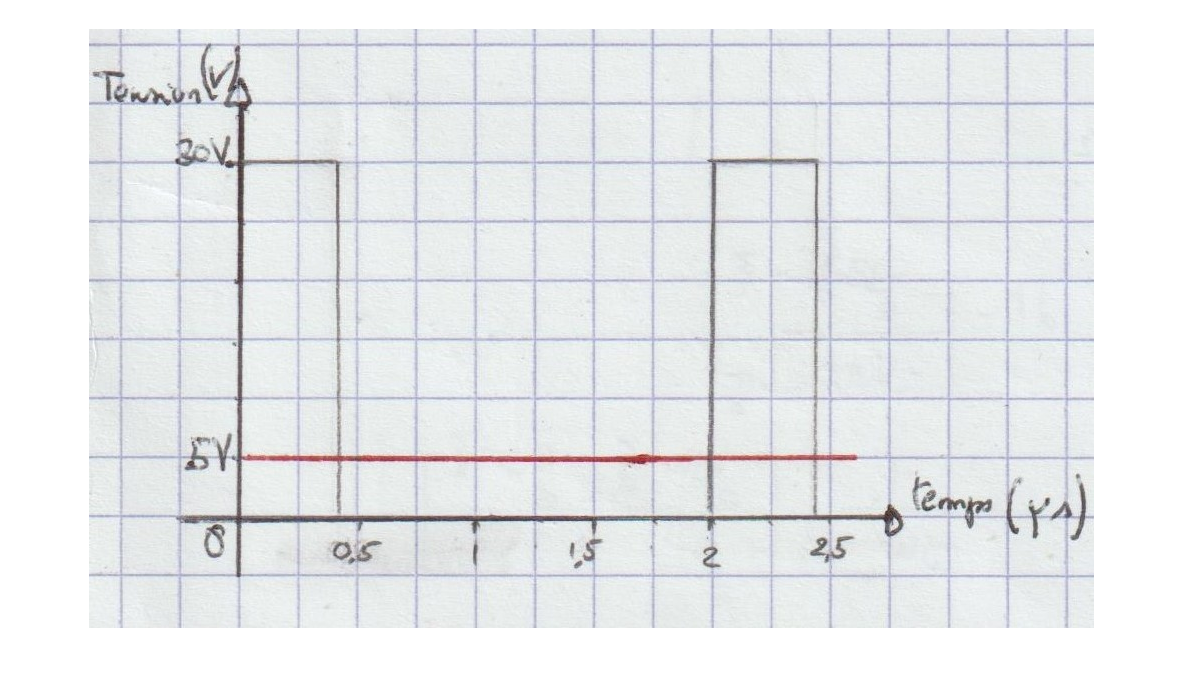

img = imread('courbe.jpg');
imshow(img);

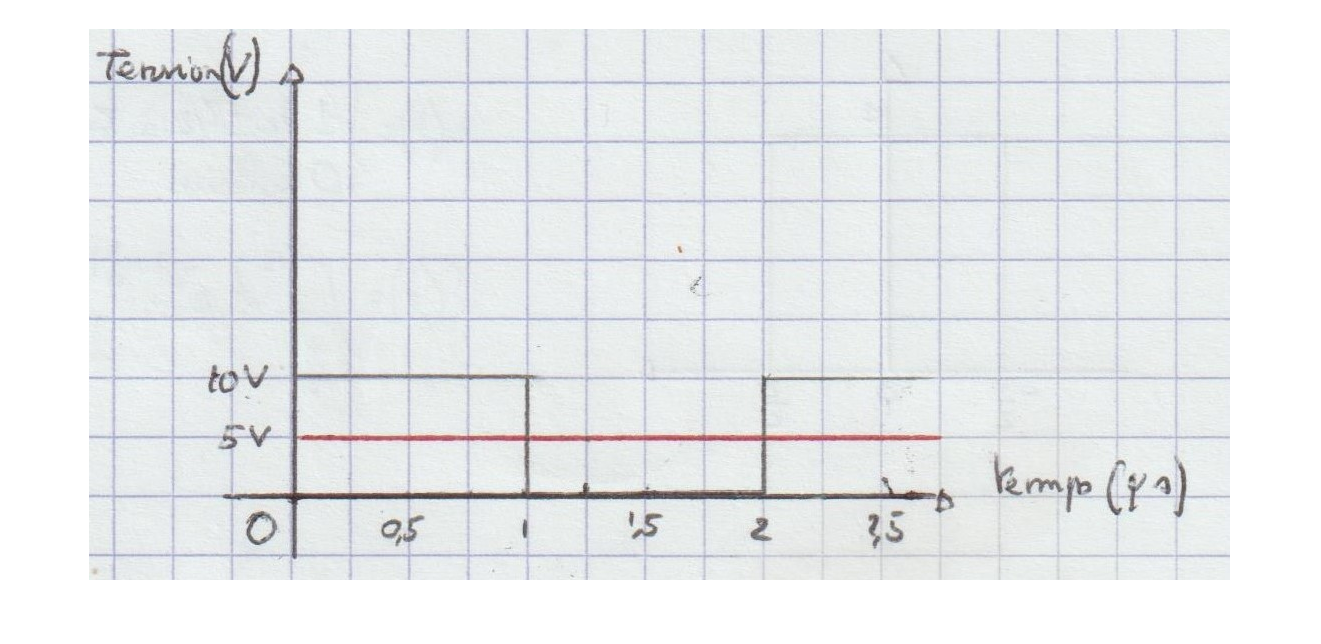

img = imread('courbe 2.jpg');
imshow(img);

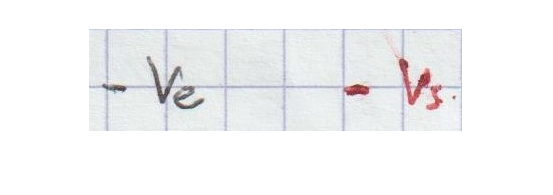

img = imread('couleur.jpg');
imshow(img);

On relève sur l'oscilloscope une fréquence de découpage environ égale à 500kHz. On note ∝ (rapport cyclique en %) le temps durant lequel le régulateur est passant (Vs=Ve) par rapport par la période totale.

Plus la tension en entrée est importante, moins le rapport cyclique est important, c'est à dire plus le temps où le régulateur est passant est petit. L'allure de cette courbe est quasi identique à celle du rendement du régulateur linéaire (à 30V, on a un pourcentage environ égal à 17% pour le rapport cyclique et le rendement du régulateur linéaire).

**On peut donc suggérer que les deux régulateurs ont le même comportement mais que c'est le rapport cyclique qui permet au régulateur à découpage de conserver un Vs à 5V qu'importe Ve et avec un η proche de 100%.**

## **II) Influence du courant de sortie**

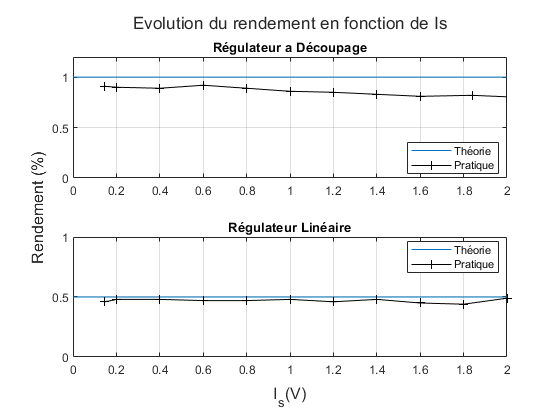

rdmth_d=[1 1 1 1 1 1 1 1 1 1 1];
Isth_d=[0 0.2 0.4 0.6 0.8 1 1.2 1.4 1.6 1.8 2];

Ve_d=[10 10 10 10 10 10 10 10 10 10 10];
Ie_d=[.08 .11 .22 .32 .43 .55 65 .77 .88 1 1.15];
Vs_d=[5 4.96 4.93 4.88 4.78 4.72 4.61 4.55 4.48 4.46 4.46];
Is_d=[.145 .2 .4 .6 .8 1 1.2 1.4 1.6 1.84 2.056];
rdm_d=[.91 .90 .89 .92 .89 .86 .85 .83 .81 .82 .80];

figure
t = tiledlayout(2,1);
title(t,'Evolution du rendement en fonction de Is')
xlabel(t,'I_s(V)')
ylabel(t,'Rendement (%)')

ax1 = nexttile;
plot(ax1,Isth_d,rdmth_d,Is_d,rdm_d,'k+-');
axis([0 2 0 1.02])
title(ax1,'Régulateur a Découpage');
legend('Théorie','Pratique','location','best')
% xlabel('I_s(A)')
% ylabel('Rendement')
grid on
ylim([0 1.2])


rdmth_l=[1 1 1 1 1 1 1 1 1 1 1]./2;
Isth_l=[0 0.2 0.4 0.6 0.8 1 1.2 1.4 1.6 1.8 2];

Ve_l=[10 10 10 10 10 10 10 10 10 10 7.15];
Ie_l=[0.16 0.21 0.41 0.62 0.82 1 1.22 1.42 1.63 1.84 2];
Vs_l=[5.04 5.02 4.96 4.89 4.83 4.77 4.71 4.82 4.54 4.46 4.06];
Is_l=[0.147 0.20 0.40 0.60 0.80 1 1.20 1.40 1.60 1.80 2.00];
rmd_l=[0.46 0.48 0.48 0.47 0.47 0.48 0.46 0.48 0.45 0.44 0.49];

ax2 = nexttile;
plot(ax2,Isth_l,rdmth_l,Is_l,rmd_l,'k+-');
axis([0 2 0 1])
title(ax2,'Régulateur Linéaire');
legend('Théorie','Pratique','location','best')
% xlabel('I_s(A)')
% ylabel('Rendement')
grid on

Encore une fois, les valeurs mesurées correspondent aux valeurs théoriques.

Le rendement pour les deux régulateurs reste identiques qu'importe le courant de sortie. En comparant les courbes, on détermine que le rendement du régulateur à découpage est bien meilleur que celui du régulateur linéaire (presque x2). A noté qu'il semble que le rendement du régulateur à découpage diminue faiblement plus le courant de sortie est faible, ce qui contredit la théorie.

On a Ve=10V constant, or le rendement étant Vs/Ve (car Is=Ie) et la tension de sortie est d'environ 5V, on a donc un rendement de 50% pour le régulateur linéaire.

Pour le régulateur a découpage le rendement est de 100% en théorie. Cela est du au circuit de commande qui adapte le courant d'entrée afin d'avoir un rendement optimal. 

En pratique, nous remarquons que le rendement est d'environ 90%, cela est surement liés aux differents pertes dans le circuit.

**En conclusion, le courant de sortie n'a aucun impact sur le rendement des deux régulateurs.**